# GCI-PFF Project Using Henderson's Method - retrograde

clear

load([cd filesep 'PFF GCI\DataInput\GCI_PFF_Data.mat' ],'GCI_PFF_Pathology_Data','GCI_PFF_Seed_Data','tpts');
load([cd filesep '\PFF GCI\DataInput\GCI_PFF_Connection.mat'],'GCI_PFF_Connection_Data');

## Retrograde Laplacian Matrix

C_Raw = GCI_PFF_Connection_Data.raw;
C_Eigen =  C_Raw/max(eig(C_Raw));
C_Eye = eye(size(C_Eigen));
C = diag(sum(C_Eigen))-C_Eigen.*(~C_Eye); % retrograde colcum(C)-C
clearvars C_Eye C_Eigen C_Raw

## Try x0 and c

x0_Val = linspace(0.001,1,100);
C_all = [linspace(1e-4,1e-2,100),linspace(1e-2,10,100)];
C_all = unique(C_all);

## MSE GCI Result

GCI_Real = GCI_PFF_Pathology_Data.GCI_Average_New;
GCI_Predict = {};
tic
for x0_Num = 1:length(x0_Val)
    x0_GCI = x0_Val(x0_Num)*GCI_PFF_Seed_Data;
    for C_Num = 1:length(C_all)
        GCI_Predict{C_Num}(:,1) = expm(-C_all(C_Num)*3*C)*x0_GCI;
        GCI_Predict{C_Num}(:,2) = expm(-C_all(C_Num)*6*C)*x0_GCI;
        GCI_PredictTemp = GCI_Predict{C_Num};
        for Time = 1:2
            GCI_MSEResult(x0_Num,C_Num,Time) = sum((GCI_PredictTemp(:,Time)-GCI_Real(:,Time)).^2,'omitnan')/length(find(isfinite(GCI_Real(:,Time))));
        end
    end
end
toc

Elapsed time is 556.845250 seconds.


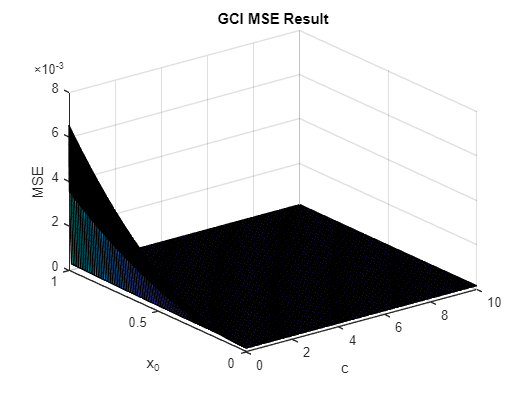

for x0_Num = 1:length(x0_Val)   
    for C_Num = 1:length(C_all)
        GCI_MSEMean(x0_Num,C_Num) = mean(GCI_MSEResult(x0_Num,C_Num,:));
    end
end
figure
surf(C_all,x0_Val,GCI_MSEMean)
title('GCI MSE Result')
xlabel('c')
ylabel('x_0')
zlabel('MSE')

[GCI_loc1,GCI_loc2] = find(GCI_MSEMean==min(min(GCI_MSEMean)));
disp(['Minimum Result = ',num2str(min(min(GCI_MSEMean)))])

Minimum Result = 0.00014835


disp(['Minimum Location:','x0=',num2str(GCI_loc1),',','c=',num2str(GCI_loc2)])

Minimum Location:x0=66,c=134


disp(['Minimum Parameters:','x0=',num2str(x0_Val(GCI_loc1)),',','c=',num2str(C_all(GCI_loc2))])

Minimum Parameters:x0=0.65691,c=3.4409


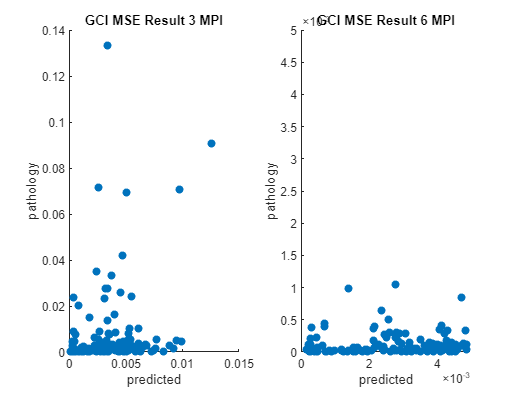

c_final_GCI = C_all(GCI_loc2);
x0_final_GCI = x0_Val(GCI_loc1);
GCI_Predict_Final(:,1) = expm(-c_final_GCI*3*C)*x0_final_GCI*GCI_PFF_Seed_Data;
GCI_Predict_Final(:,2) = expm(-c_final_GCI*6*C)*x0_final_GCI*GCI_PFF_Seed_Data;
GCI_NotNANFind = find(isnan(sum(GCI_Real,2))==0);
figure()
subplot(1,2,1)
scatter(GCI_Predict_Final(GCI_NotNANFind,1),GCI_Real(GCI_NotNANFind,1),'filled')
title('GCI MSE Result 3 MPI')
xlabel('predicted')
ylabel('pathology')
subplot(1,2,2)
scatter(GCI_Predict_Final(GCI_NotNANFind,2),GCI_Real(GCI_NotNANFind,2),'filled')
axis([0 5e-3,0 5e-3])
title('GCI MSE Result 6 MPI')
xlabel('predicted')
ylabel('pathology')

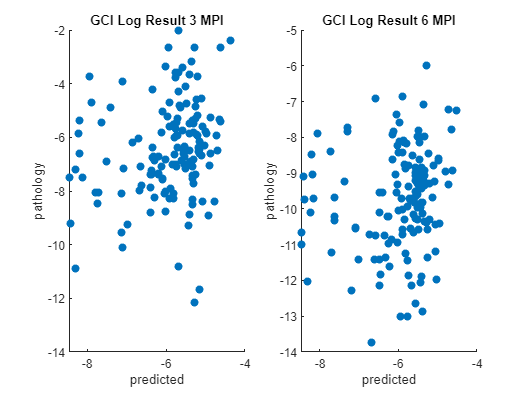

% Calculate R^2 after log
GCI_Predict_Final_Log = log(GCI_Predict_Final);
GCI_Real_Log = log(GCI_Real);
GCI_FiniteFind_Log = find(isfinite(sum(GCI_Real_Log,2)));
figure()
subplot(1,2,1)
scatter(GCI_Predict_Final_Log(GCI_FiniteFind_Log,1),GCI_Real_Log(GCI_FiniteFind_Log,1),'filled')
title('GCI Log Result 3 MPI')
xlabel('predicted')
ylabel('pathology')
subplot(1,2,2)
scatter(GCI_Predict_Final_Log(GCI_FiniteFind_Log,2),GCI_Real_Log(GCI_FiniteFind_Log,2),'filled')
title('GCI Log Result 6 MPI')
xlabel('predicted')
ylabel('pathology')


GCI_Log_MSE_Corr_3MPI = corrcoef(GCI_Predict_Final_Log(GCI_FiniteFind_Log,1),GCI_Real_Log(GCI_FiniteFind_Log,1));
GCI_Log_MSE_Corr_6MPI = corrcoef(GCI_Predict_Final_Log(GCI_FiniteFind_Log,2),GCI_Real_Log(GCI_FiniteFind_Log,2));

disp(['GCI_R_3MPI=',num2str(GCI_Log_MSE_Corr_3MPI(2))])

GCI_R_3MPI=0.21454


disp(['GCI_R_6MPI=',num2str(GCI_Log_MSE_Corr_6MPI(2))])

GCI_R_6MPI=0.15274


## MSE PFF Result

PFF_Real = GCI_PFF_Pathology_Data.PFF_Average;
PFF_Predict = {};
tic
for x0_Num = 1:length(x0_Val)
    x0_PFF = x0_Val(x0_Num)*GCI_PFF_Seed_Data;
    for C_Num = 1:length(C_all)
        PFF_Predict{C_Num}(:,1) = expm(-C_all(C_Num)*3*C)*x0_PFF;
        PFF_Predict{C_Num}(:,2) = expm(-C_all(C_Num)*6*C)*x0_PFF;
        PFF_PredictTemp = PFF_Predict{C_Num};
        for Time = 1:2
            PFF_MSEResult(x0_Num,C_Num,Time) = sum((PFF_PredictTemp(:,Time)-PFF_Real(:,Time)).^2,'omitnan')/length(find(isfinite(PFF_Real(:,Time))));
        end
    end
end
toc

Elapsed time is 562.503213 seconds.


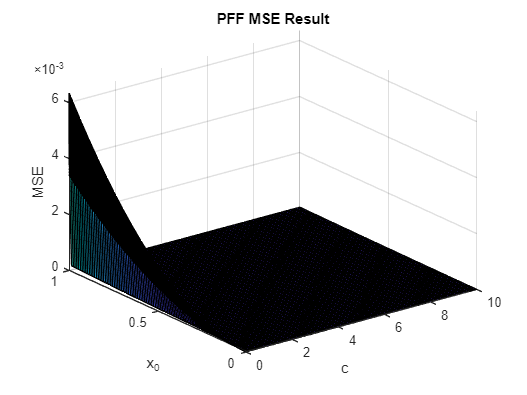

for x0_Num = 1:length(x0_Val)   
    for C_Num = 1:length(C_all)
        PFF_MSEMean(x0_Num,C_Num) = mean(PFF_MSEResult(x0_Num,C_Num,:));
    end
end
figure
surf(C_all,x0_Val,PFF_MSEMean)
title('PFF MSE Result')
xlabel('c')
ylabel('x_0')
zlabel('MSE')

[PFF_loc1,PFF_loc2] = find(PFF_MSEMean==min(min(PFF_MSEMean)));
disp(['Minimum Result = ',num2str(min(min(PFF_MSEMean)))])

Minimum Result = 6.2098e-08


disp(['Minimum Location:','x0=',num2str(PFF_loc1),',','c=',num2str(PFF_loc2)])

Minimum Location:x0=3,c=105


disp(['Minimum Parameters:','x0=',num2str(x0_Val(PFF_loc1)),',','c=',num2str(C_all(PFF_loc2))])

Minimum Parameters:x0=0.021182,c=0.51455


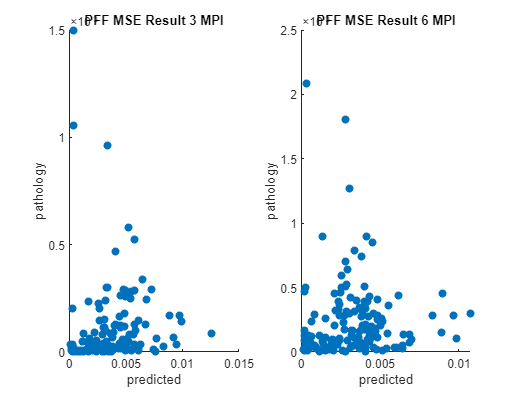

c_final_PFF = C_all(GCI_loc2);
x0_final_PFF = x0_Val(GCI_loc1);
PFF_Predict_Final(:,1) = expm(-c_final_PFF*3*C)*x0_final_PFF*GCI_PFF_Seed_Data;
PFF_Predict_Final(:,2) = expm(-c_final_PFF*6*C)*x0_final_PFF*GCI_PFF_Seed_Data;
PFF_NotNANFind = find(isnan(sum(PFF_Real,2))==0);
figure()
subplot(1,2,1)
scatter(PFF_Predict_Final(PFF_NotNANFind,1),PFF_Real(PFF_NotNANFind,1),'filled')
title('PFF MSE Result 3 MPI')
xlabel('predicted')
ylabel('pathology')
subplot(1,2,2)
scatter(PFF_Predict_Final(PFF_NotNANFind,2),PFF_Real(PFF_NotNANFind,2),'filled')
title('PFF MSE Result 6 MPI')
xlabel('predicted')
ylabel('pathology')

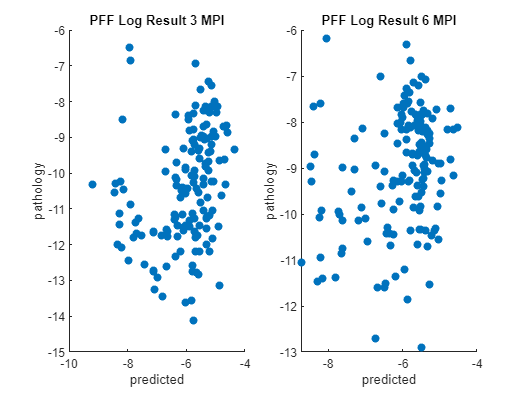

% Calculate R^2 after log
PFF_Predict_Final_Log = log(PFF_Predict_Final);
PFF_Real_Log = log(PFF_Real);
PFF_FiniteFind_Log = find(isfinite(sum(PFF_Real_Log,2)));
figure()
subplot(1,2,1)
scatter(PFF_Predict_Final_Log(PFF_FiniteFind_Log,1),PFF_Real_Log(PFF_FiniteFind_Log,1),'filled')
title('PFF Log Result 3 MPI')
xlabel('predicted')
ylabel('pathology')
subplot(1,2,2)
scatter(PFF_Predict_Final_Log(PFF_FiniteFind_Log,2),PFF_Real_Log(PFF_FiniteFind_Log,2),'filled')
title('PFF Log Result 6 MPI')
xlabel('predicted')
ylabel('pathology')


PFF_Log_MSE_Corr_3MPI = corrcoef(PFF_Predict_Final_Log(PFF_FiniteFind_Log,1),PFF_Real_Log(PFF_FiniteFind_Log,1));
PFF_Log_MSE_Corr_6MPI = corrcoef(PFF_Predict_Final_Log(PFF_FiniteFind_Log,2),PFF_Real_Log(PFF_FiniteFind_Log,2));

disp(['PFF_R_3MPI=',num2str(PFF_Log_MSE_Corr_3MPI(2))])

PFF_R_3MPI=0.29797


disp(['PFF_R_6MPI=',num2str(PFF_Log_MSE_Corr_6MPI(2))])

PFF_R_6MPI=0.26032


## Best R^2 GCI Result

Log_GCI_Real = log(GCI_PFF_Pathology_Data.GCI_Average_New);
Log_GCI_Real_FiniteLoc = find(isfinite(sum(Log_GCI_Real,2)));
tic
for x0_Num = 1:length(x0_Val)
    x0_GCI = x0_Val(x0_Num)*GCI_PFF_Seed_Data;
    for C_Num = 1:length(C_all)
        GCI_Predict{C_Num}(:,1) = expm(-C_all(C_Num)*3*C)*x0_GCI;
        GCI_Predict{C_Num}(:,2) = expm(-C_all(C_Num)*6*C)*x0_GCI;
        Log_GCI_PredictTemp = log(GCI_Predict{C_Num});
        Log_GCI_PredictTemp_FiniteLoc = find(isfinite(sum(Log_GCI_PredictTemp,2)));
        Log_GCI_Predict_Real_FiniteLoc = intersect(Log_GCI_PredictTemp_FiniteLoc,Log_GCI_Real_FiniteLoc);
        for Time = 1:2
            GCI_R_Result_Temp = corrcoef(Log_GCI_Real(Log_GCI_Predict_Real_FiniteLoc,Time),Log_GCI_PredictTemp(Log_GCI_Predict_Real_FiniteLoc,Time));
            GCI_R_Result(x0_Num,C_Num,Time) = GCI_R_Result_Temp(2);
        end
        GCI_R(x0_Num,C_Num) = mean(GCI_R_Result(x0_Num,C_Num,:));
    end
end
toc

Elapsed time is 570.959788 seconds.


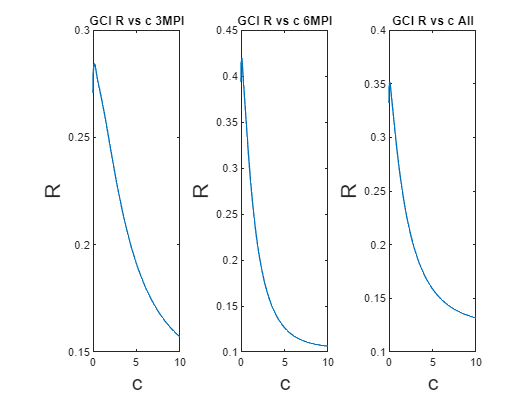

figure
subplot(1,3,1)
plot(C_all,GCI_R_Result(1,:,1))
title('GCI R vs c 3MPI')
xlabel('c','Fontsize',16)
ylabel('R','Fontsize',16)
subplot(1,3,2)
plot(C_all,GCI_R_Result(1,:,2))
title('GCI R vs c 6MPI')
xlabel('c','Fontsize',16)
ylabel('R','Fontsize',16)
subplot(1,3,3)
plot(C_all,GCI_R(1,:))
title('GCI R vs c All')
xlabel('c','Fontsize',16)
ylabel('R','Fontsize',16)


disp(['GCI R Best 3MPI = ',num2str(max(GCI_R_Result(1,:,1))),';     ','Best Location: C = ',num2str(C_all(find(GCI_R_Result(1,:,1)==max(GCI_R_Result(1,:,1)))))])

GCI R Best 3MPI = 0.2842;     Best Location: C = 0.21182


disp(['GCI R Best 6MPI = ',num2str(max(GCI_R_Result(1,:,2))),';     ','Best Location: C= ',num2str(C_all(find(GCI_R_Result(1,:,2)==max(GCI_R_Result(1,:,2)))))])

GCI R Best 6MPI = 0.41929;     Best Location: C= 0.11091


disp(['GCI R Best All = ',num2str(max(GCI_R(1,:))),';     ','Best Location: C = ',num2str(C_all(find(GCI_R(1,:)==max(GCI_R(1,:)))))])

GCI R Best All = 0.35171;     Best Location: C = 0.11091


## Best R^2 PFF Result

Log_PFF_Real = log(GCI_PFF_Pathology_Data.PFF_Average);
Log_PFF_Real_FiniteLoc = find(isfinite(sum(Log_PFF_Real,2)));
tic
for x0_Num = 1:length(x0_Val)
    x0_PFF = x0_Val(x0_Num)*GCI_PFF_Seed_Data;
    for C_Num = 1:length(C_all)
        PFF_Predict{C_Num}(:,1) = expm(-C_all(C_Num)*3*C)*x0_PFF;
        PFF_Predict{C_Num}(:,2) = expm(-C_all(C_Num)*6*C)*x0_PFF;
        Log_PFF_PredictTemp = log(PFF_Predict{C_Num});
        Log_PFF_PredictTemp_FiniteLoc = find(isfinite(sum(Log_PFF_PredictTemp,2)));
        Log_PFF_Predict_Real_FiniteLoc = intersect(Log_PFF_PredictTemp_FiniteLoc,Log_PFF_Real_FiniteLoc);
        for Time = 1:2
            PFF_R_Result_Temp = corrcoef(Log_PFF_Real(Log_PFF_Predict_Real_FiniteLoc,Time),Log_PFF_PredictTemp(Log_PFF_Predict_Real_FiniteLoc,Time));
            PFF_R_Result(x0_Num,C_Num,Time) = PFF_R_Result_Temp(2);
        end
        PFF_R(x0_Num,C_Num) = mean(PFF_R_Result(x0_Num,C_Num,:));
    end
end
toc

Elapsed time is 566.449419 seconds.


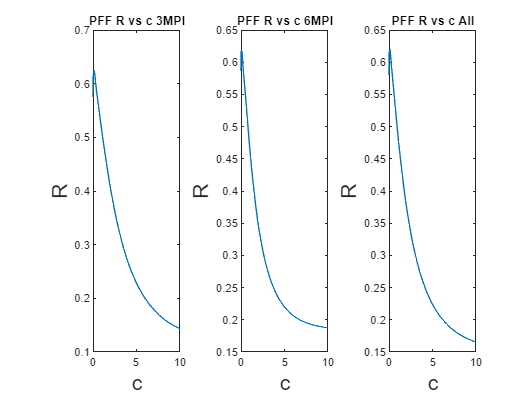

figure
subplot(1,3,1)
plot(C_all,PFF_R_Result(1,:,1))
title('PFF R vs c 3MPI')
xlabel('c','Fontsize',16)
ylabel('R','Fontsize',16)
subplot(1,3,2)
plot(C_all,PFF_R_Result(1,:,2))
title('PFF R vs c 6MPI')
xlabel('c','Fontsize',16)
ylabel('R','Fontsize',16)
subplot(1,3,3)
plot(C_all,PFF_R(1,:))
title('PFF R vs c All')
xlabel('c','Fontsize',16)
ylabel('R','Fontsize',16)


disp(['PFF R Best 3MPI = ',num2str(max(PFF_R_Result(1,:,1))),';     ','Best Location: C = ',num2str(C_all(find(PFF_R_Result(1,:,1)==max(PFF_R_Result(1,:,1)))))])

PFF R Best 3MPI = 0.6246;     Best Location: C = 0.11091


disp(['PFF R Best 6MPI = ',num2str(max(PFF_R_Result(1,:,2))),';     ','Best Location: C= ',num2str(C_all(find(PFF_R_Result(1,:,2)==max(PFF_R_Result(1,:,2)))))])

PFF R Best 6MPI = 0.61743;     Best Location: C= 0.11091


disp(['PFF R Best All = ',num2str(max(PFF_R(1,:))),';     ','Best Location: C = ',num2str(C_all(find(PFF_R(1,:)==max(PFF_R(1,:)))))])

PFF R Best All = 0.62102;     Best Location: C = 0.11091
